# Dynamics - Euler-Lagrange II

clear all;
clc;

## 1) Parameters

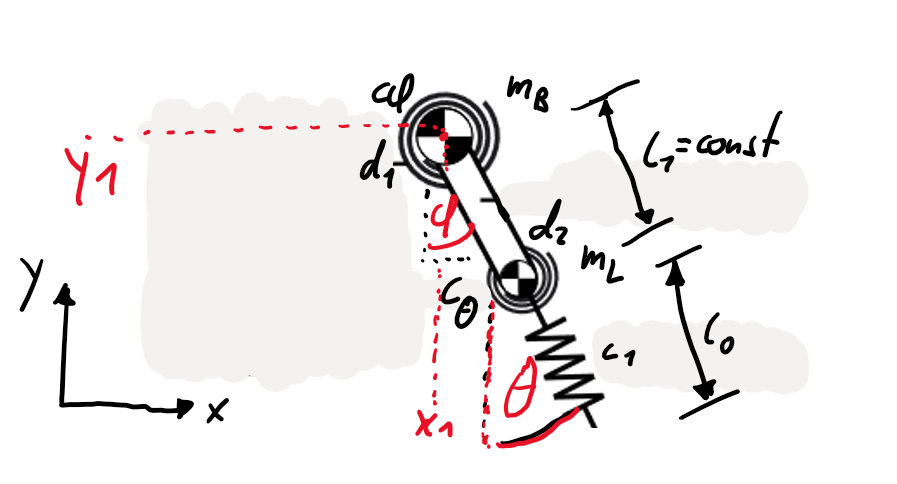

#### 1_1) Physical parameters

syms m_L; % kg; Mass of leg, concentrated as point mass in knee
syms m_B; % kg; Mass of upper body, concentrated as point mass in hip

syms d_1; % N*s/rad; Rotational damper in hip
syms d_2; % N*s/rad; Rotational damper in knee

syms c_phi; % N/rad; Rotational spring in hip
syms c_theta; % N/rad; Rotational spring in knee
syms c_1; % N/m; Translational spring attached to knee

syms l_1; % m, Length of leg-segment between knee and hip
syms l_0; % m, Initial length of translational spring at knee

syms g_earth;
g = [0; g_earth]; % m/s^2; Gravitational acceleration

#### 1_2) Dynamic parameters

syms t x(t) y(t) phi(t) theta(t);
q = [x(t); y(t); phi(t); theta(t)]; % Vector of generalized coordinates, see picture for more information

## 2) Position vectors of point masses

syms x_1(t) y_1(t); % Absolut position of hip

r_mB = [x_1(t); y_1(t)]; %Position of hip
r_mL = [x_1(t) + sin(phi(t))*l_1; y_1(t) - cos(phi(t))*l_1]; %Position of knee

%Velocity
d_r_mB = diff(r_mB);
d_r_mL = diff(r_mL);
%Acceleration
dd_r_mB = diff(d_r_mB);
dd_r_mL = diff(d_r_mL);

## 3) Terms for Euler-Lagrange

#### 3_1) Kinetic_Energy

T_B = 0.5 * m_B * (d_r_mB' * d_r_mB); % Kinetic energy of hip

T_L = 0.5 * m_L * (d_r_mL' * d_r_mL); % Kinetic energy of knee

T = simplify(T_B + T_L) % Total kinetic energy

$$T = \begin{array}{l} \frac{m_{B}\,\left(\sigma_{2}\,\frac{\partial }{\partial t}x_{1}\left(t\right)+\sigma_{1}\,\frac{\partial }{\partial t}y_{1}\left(t\right)\right)}{2}+\frac{m_{L}\,\left(\left(\sigma_{2}+\sigma_{3}\,\cos\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)\,\left(\frac{\partial }{\partial t}x_{1}\left(t\right)+l_{1}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)+\left(\frac{\partial }{\partial t}y_{1}\left(t\right)+l_{1}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)\,\left(\sigma_{1}+\sigma_{3}\,\sin\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)\right)}{2}\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}y_{1}\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}x_{1}\left(t\right)}\\ \sigma_{3}=\bar{\frac{\partial }{\partial t}\varphi \left(t\right)} \end{array}$$

#### 3_2) Potential_Energy

V_G = - m_B * (r_mB' * g) - m_L * (r_mL' * g); % Gravitational potential energy

V_rotC = c_phi * phi(t) + c_theta * theta(t); % Rotational spring energy

l = sqrt(r_mL' * r_mL); % m; current length of translational spring
V_c = c_1 * (l - l_0); % Translational spring energy

V = simplify(V_G + V_rotC + V_c) % Total potential energy

$$V = \begin{array}{l} c_{\varphi }\,\varphi \left(t\right)-c_{1}\,\left(l_{0}-\sqrt{\left(y_{1}\left(t\right)-l_{1}\,\cos\left(\varphi \left(t\right)\right)\right)\,\sigma_{1}+\left(x_{1}\left(t\right)+l_{1}\,\sin\left(\varphi \left(t\right)\right)\right)\,\left(\bar{x_{1}\left(t\right)}+\sin\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}}\right)}\right)+c_{\theta }\,\theta \left(t\right)-g_{\mathrm{earth}}\,m_{B}\,\bar{y_{1}\left(t\right)}-g_{\mathrm{earth}}\,m_{L}\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\bar{y_{1}\left(t\right)}-\cos\left(\bar{\varphi \left(t\right)}\right)\,\bar{l_{1}} \end{array}$$

#### 3_3) Non-conservative forces

X_1 = -d_1 * diff(phi(t)) * [-cos(phi(t)); - sin(phi(t))];
X_2 = -d_2 * diff(theta(t)) * [-cos(theta(t)); - sin(theta(t))];

%Help variables for calculating the differentiations
xx = sym('x_1');
yy = sym('y_1');
phiphi = sym('phi');
thetatheta = sym('theta');

dx_r_mB = subs(diff(subs(r_mB,x_1,xx),xx),xx,x_1);
dx_r_mL = subs(diff(subs(r_mL,x_1,xx),xx),xx,x_1);

dy_r_mB = subs(diff(subs(r_mB,y_1,yy),yy),yy,y_1);
dy_r_mL = subs(diff(subs(r_mL,y_1,yy),yy),yy,y_1);

dphi_r_mB = subs(diff(subs(r_mB,phi,phiphi),phiphi),phiphi,phi);
dphi_r_mL = subs(diff(subs(r_mL,phi,phiphi),phiphi),phiphi,phi);

dtheta_r_mB = subs(diff(subs(r_mB,theta,thetatheta),thetatheta),thetatheta,theta);
dtheta_r_mL = subs(diff(subs(r_mL,theta,thetatheta),thetatheta),thetatheta,theta);


Q_nc_x = (dx_r_mB)' * X_1 + (dx_r_mL)' * X_2;
Q_nc_y = (dy_r_mB)' * X_1 + (dy_r_mL)' * X_2;
Q_nc_phi = (dphi_r_mB)' * X_1 + (dphi_r_mL)' * X_2;
Q_nc_theta = (dtheta_r_mB)' * X_1 + (dtheta_r_mL)' * X_2;

Q_nc = simplify([Q_nc_x; Q_nc_y; Q_nc_phi; Q_nc_theta]) %Vector of non-conservative forces

$$Q\_nc = \left(\begin{array}{c} d_{1}\,\cos\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+d_{2}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ d_{1}\,\sin\left(\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+d_{2}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ d_{2}\,\cos\left(\bar{\varphi \left(t\right)}-\theta \left(t\right)\right)\,\bar{l_{1}}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

## 4) Applying Euler-Lagrange II

%Using the matlab toolbox